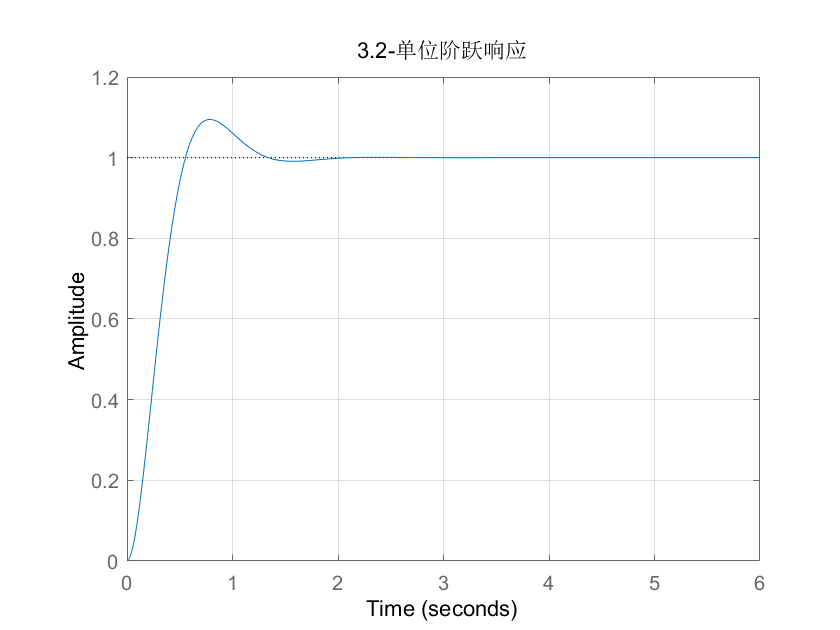

%3.2
clear
num = [25];
den = [1 6 25];  %系统闭环传递函数
t = 0:0.02:6;
step(num, den, t);  %系统单位阶跃响应
grid on
title('3.2-单位阶跃响应')

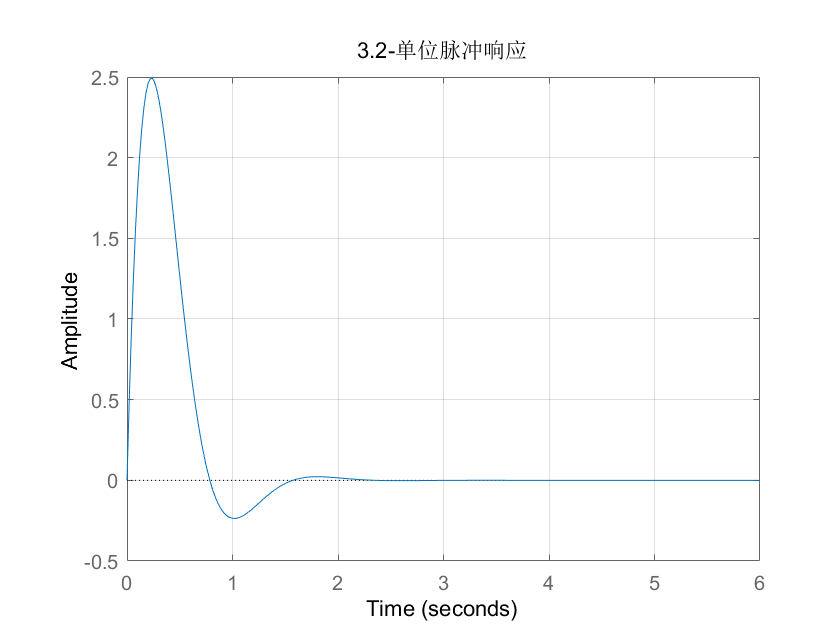

impulse(num, den, t);  %系统单位脉冲响应
title('3.2-单位脉冲响应')
grid on

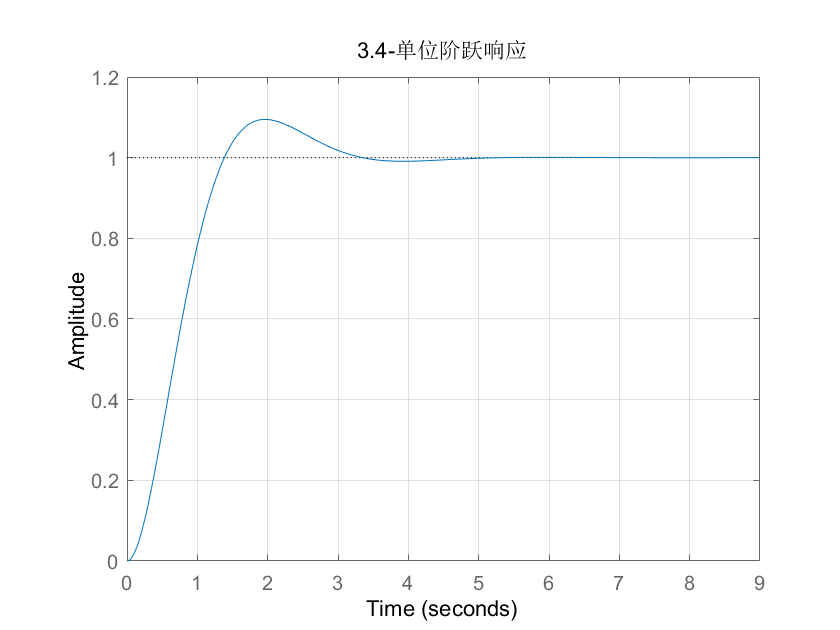


%3.4
clear
wn = [2];
kos = [0.6];
num = wn^2;
den = [1,2*wn*kos,wn^2];  %系统闭环传递函数
t = 0:0.01:9;
step(num,den,t);   %系统单位阶跃响应
title('3.4-单位阶跃响应')
grid on

% 3.5
%%建立闭环传递函数模型
clear
numg = [0.4 1];
deng = [1 0.6 0];
numh = [1];
denh = [1];
[num, den] = feedback(numg, deng, numh, denh)

num =          0    0.4000    1.0000


den =      1     1     1


sys = tf(num, den);
%%计算系统特征根判断系统稳定性
p = roots(den)

p =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


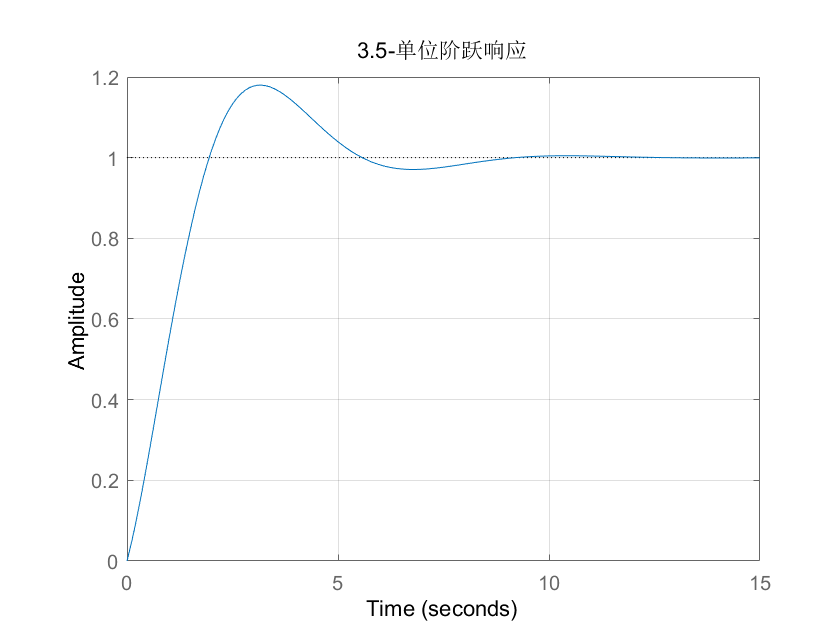

%%求取系统的单位阶跃响应
figure
t = 0:0.1:15;
step(sys, t);
title('3.5-单位阶跃响应')
grid on

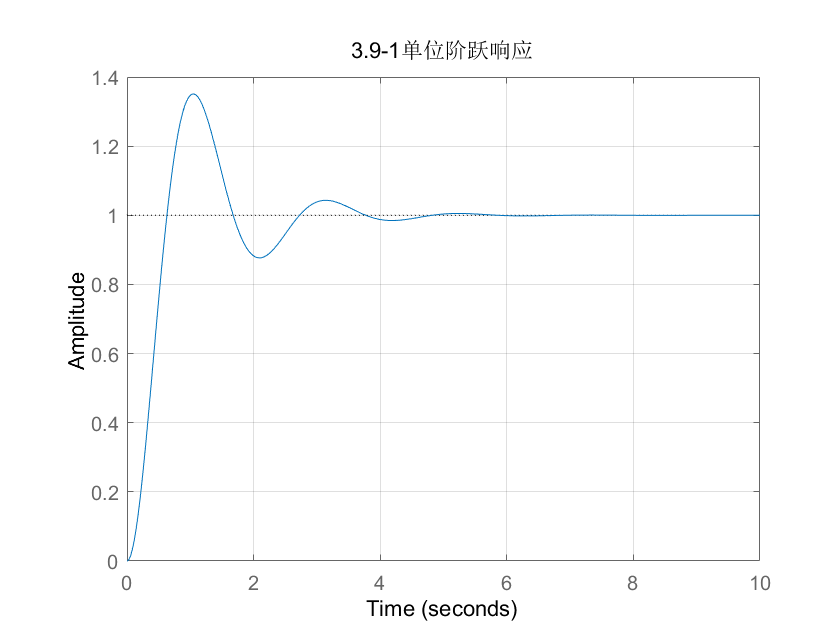

% 3.9
%%测速反馈矫正系统闭环传递函数
clear
num1 = [10];
den1 = [1 2 10];
sys1 = tf(num1, den1);
%%比例微分矫正系统闭环传递函数
num2 = [1 10];
den2 = [1 2 10];
sys2 = tf(num2, den2);
%%求取各系统的单位阶跃响应
t = 0:0.01:10;
figure(1)
step(sys1, t);
title('3.9-1单位阶跃响应')
grid on

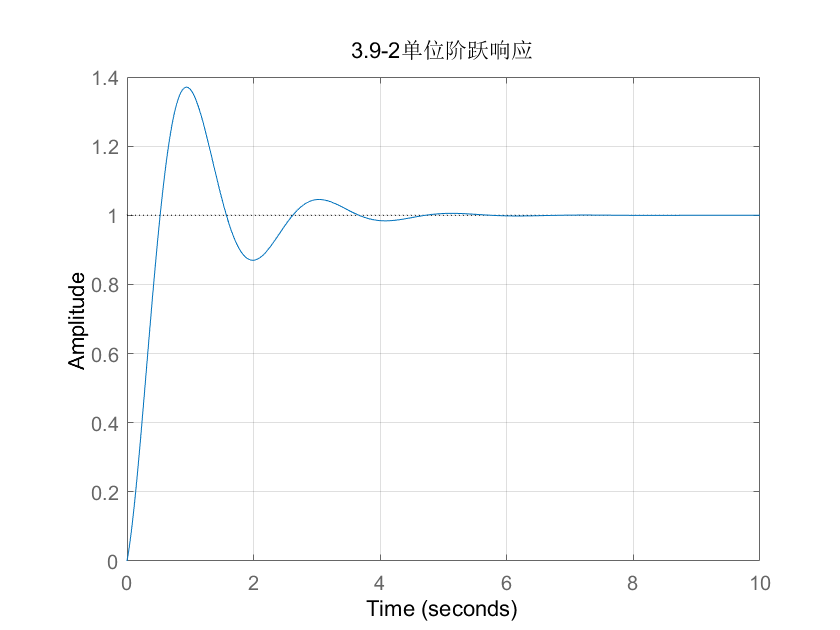

figure(2)
step(sys2, t);
title('3.9-2单位阶跃响应')
grid on

% 3.11
clear
den = [3 10 5 1 2];%系统特征方程
p = roots(den)%计算系统特征跟

p =   -2.7362 + 0.0000i
  -0.8767 + 0.0000i
   0.1398 + 0.5083i
   0.1398 - 0.5083i


% 3.13
clear
%k的取值
K = [0.2 0.7 1.2 1.7]

K =     0.2000    0.7000    1.2000    1.7000


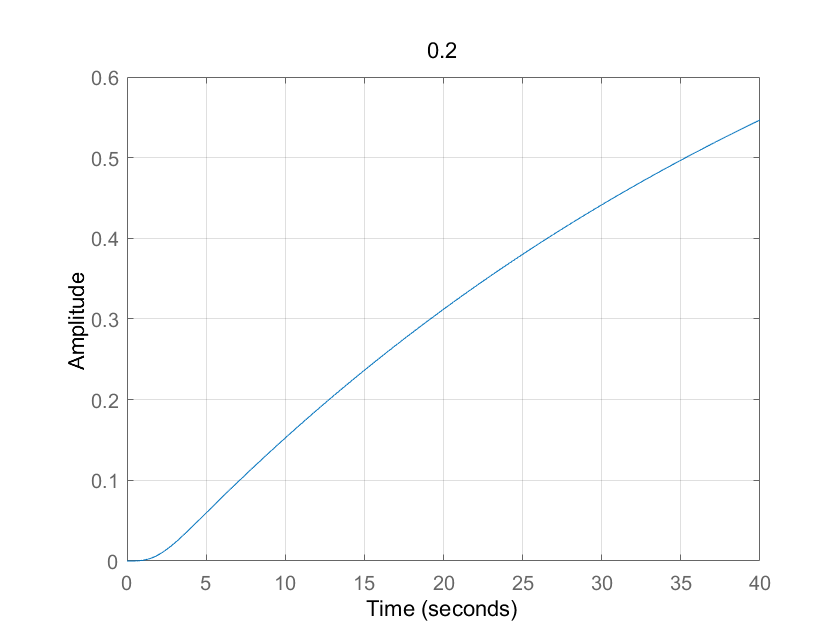

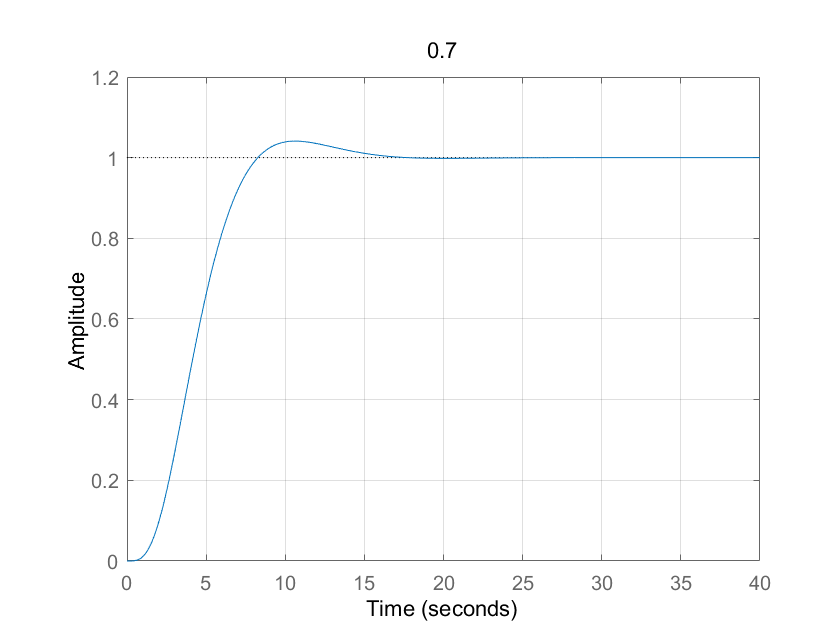

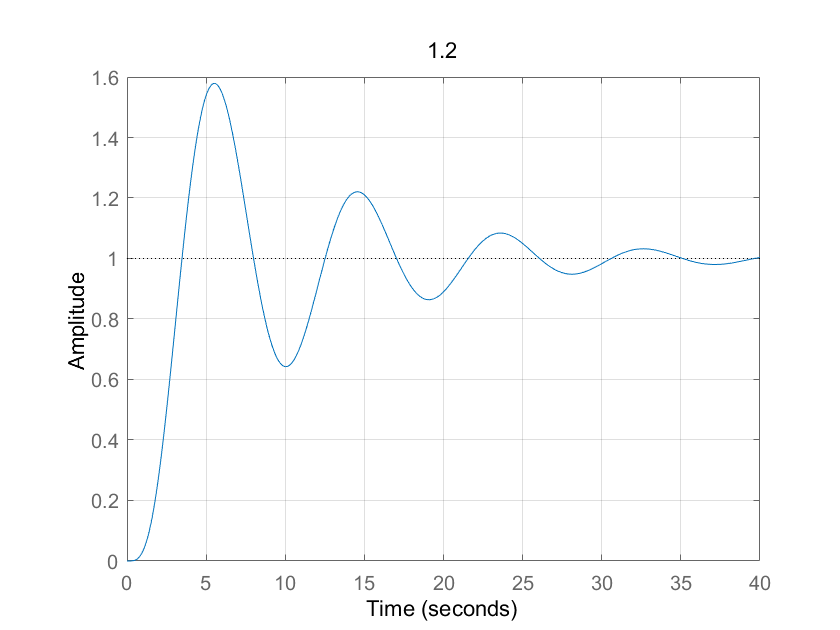

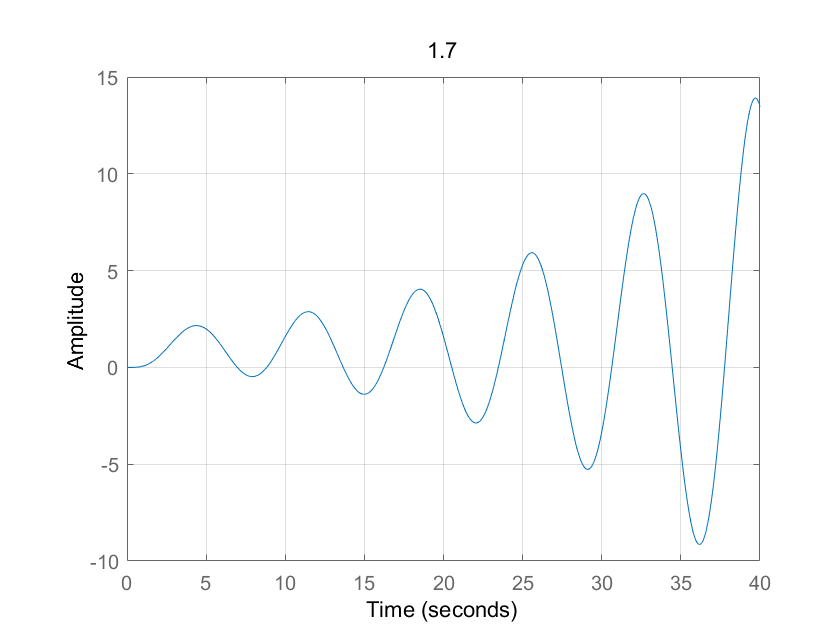

%各系统的闭环传递函数以及单位阶跃响应
t = 0:0.01:40;
for i = 1:4
    k = K(i);
    numg = [0.5*k*k];
    deng = [0.5 1.5 2 1 0];
    numh = [1];
    denh = [1];
    [num, den] = feedback(numg, deng, numh, denh);
    sys = tf(num, den);
    figure(i)
    step(sys, t);
    title(K(i))
    grid on;
end

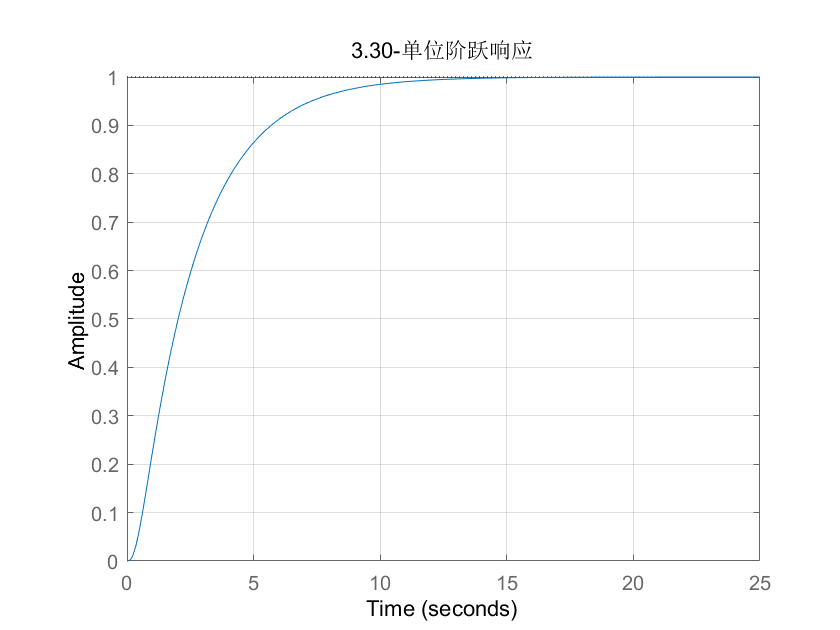

% 3.30
clear
%系统的单位阶跃响应
num = [10];
den = [1 10 27 10];
t = 0:0.05:25;
figure
step(num, den, t);
title('3.30-单位阶跃响应')
grid on